# Analiza częstotliwościowa

generowanie probek:

N = 100;
fs1kHz = 1000;
x = 50*sin(2*pi*50*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    100*sin(2*pi*100*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    150*sin(2*pi*150*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]);

% begin exc01
wk = @(k,n) sk(k,N)*cos(pi*(k/N)*(n+0.5));

% generate matrix A
A = zeros(N,N);
for k=0:N-1
    for n=0:N-1
        A(k+1,n+1) = wk(k,n);
    end
end
% end exc01

% begin exc02
S = A.';
% end exc02

prezentacja danych:

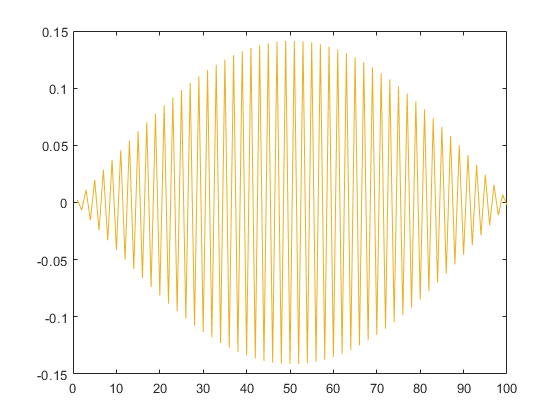

clf
figure
for i=1:N
    %A(N,:)
    %S(:,N)
    plot(1:N,A(N,:))
    plot(1:N,S(:,N)')
    hold on
    pause(0.1)
end

function s = sk(k,N)
    if k==0
        s = sqrt(1/N);
        return
    end
    s = sqrt(2/N);
end